# Regelungstechniklabor Laborversuch 5 - Schwebekugel

m=10e-3;
c_i=0.01;
c_y=0.01e2;
L=0.1;
R=5;

## Aufgabe 1

#### a)


$$G\left(s\right)=\frac{c_i }{R+\textrm{Ls}}\cdot \frac{1}{\textrm{ms²}-c_y }$$


Aus der Übertragungsfunktion erhalten wir die Pole:

${\textrm{Pol}}_1 =-\frac{R}{L}$ und ${\textrm{Pol}}_{2,3} =\pm \sqrt{\frac{c_y }{m}}$

#### b)

Da ${\textrm{Pol}}_2 =+\sqrt{\frac{c_y }{m}}$  größer 0 ist, ist die Regelstrecke instalbil.

#### c)

Simulink Model mit Sprung am Eingang.

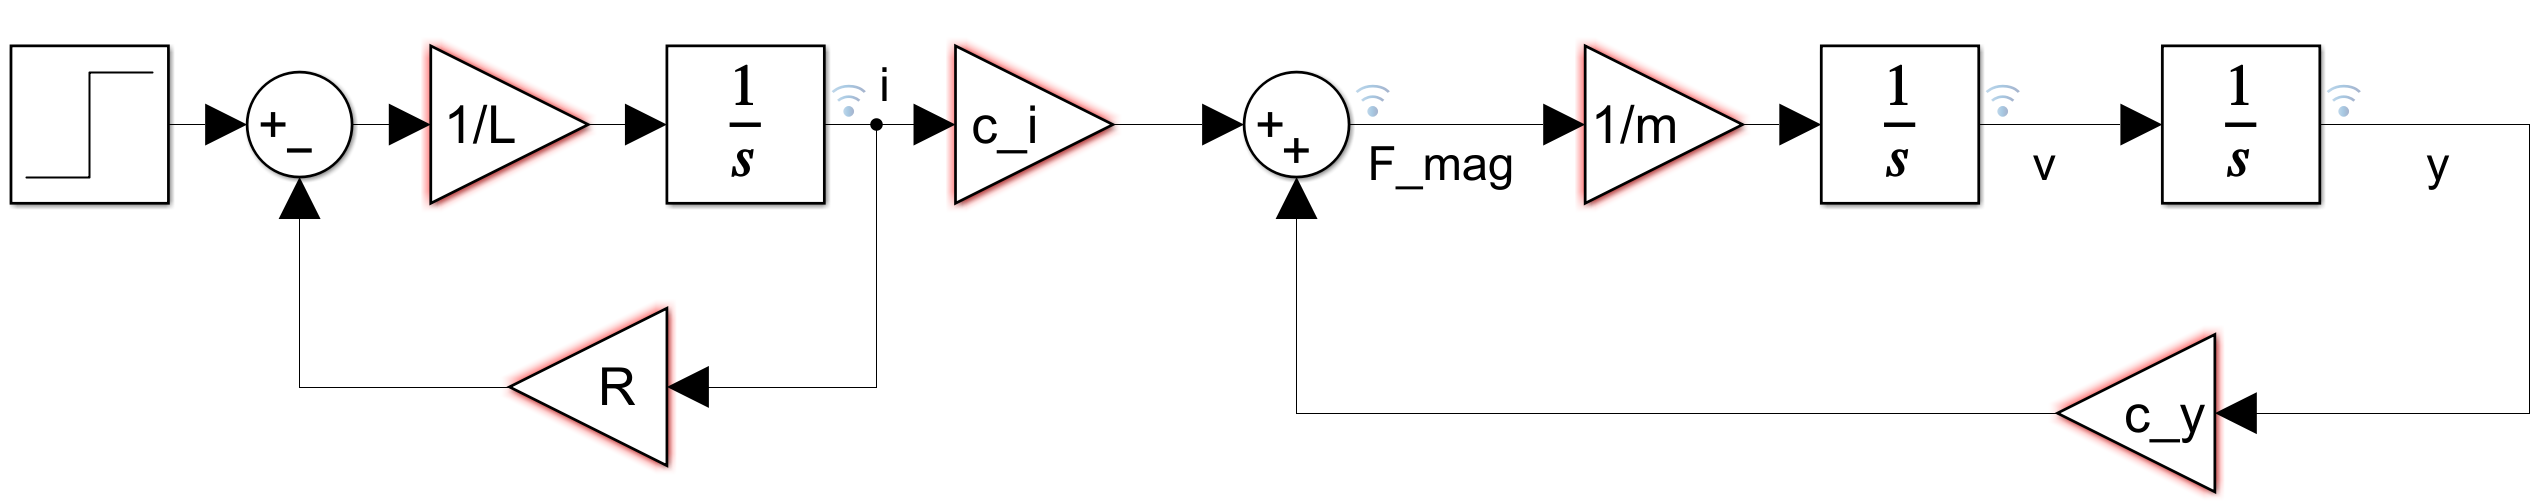

#### d)

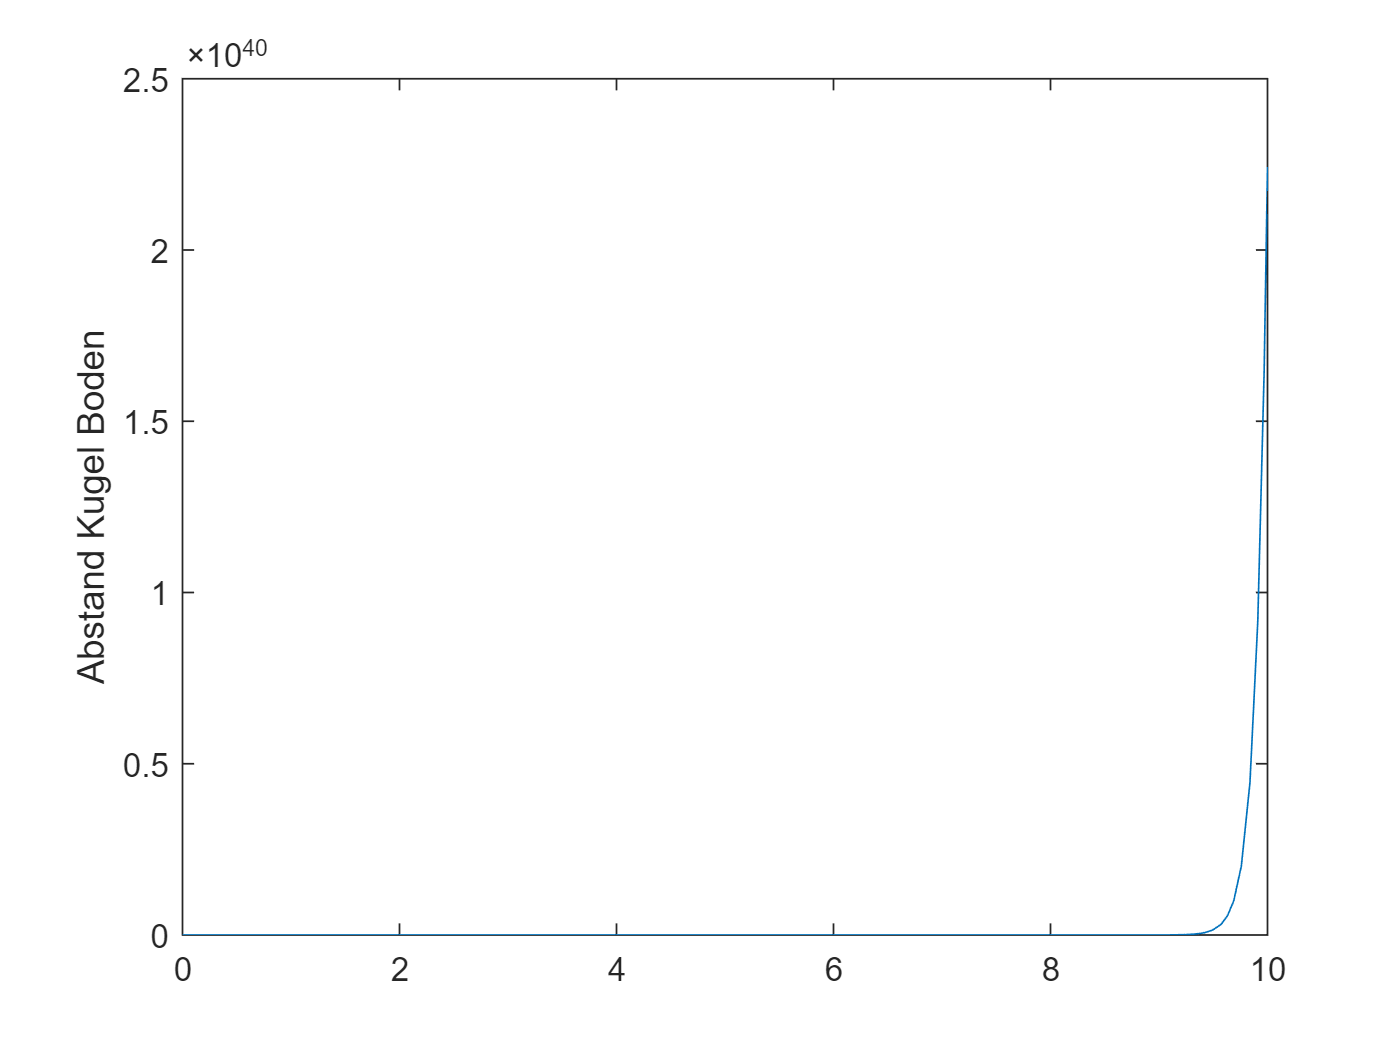

simOut = sim('L5A1.slx');
figure
plot(get(simOut.logsout,"y").Values.Time,get(simOut.logsout,"y").Values.Data);
ylabel('Abstand Kugel Boden')

#### e)

Was beobachten sie?

- Die Regelstrecke ist instabil.

## Aufgabe 2 - Regelkreis mit P-Regler

#### a)

Simulink Model:

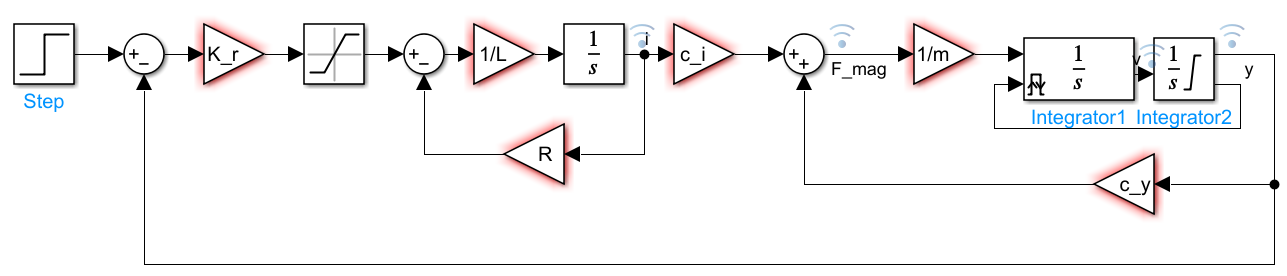

#### b)

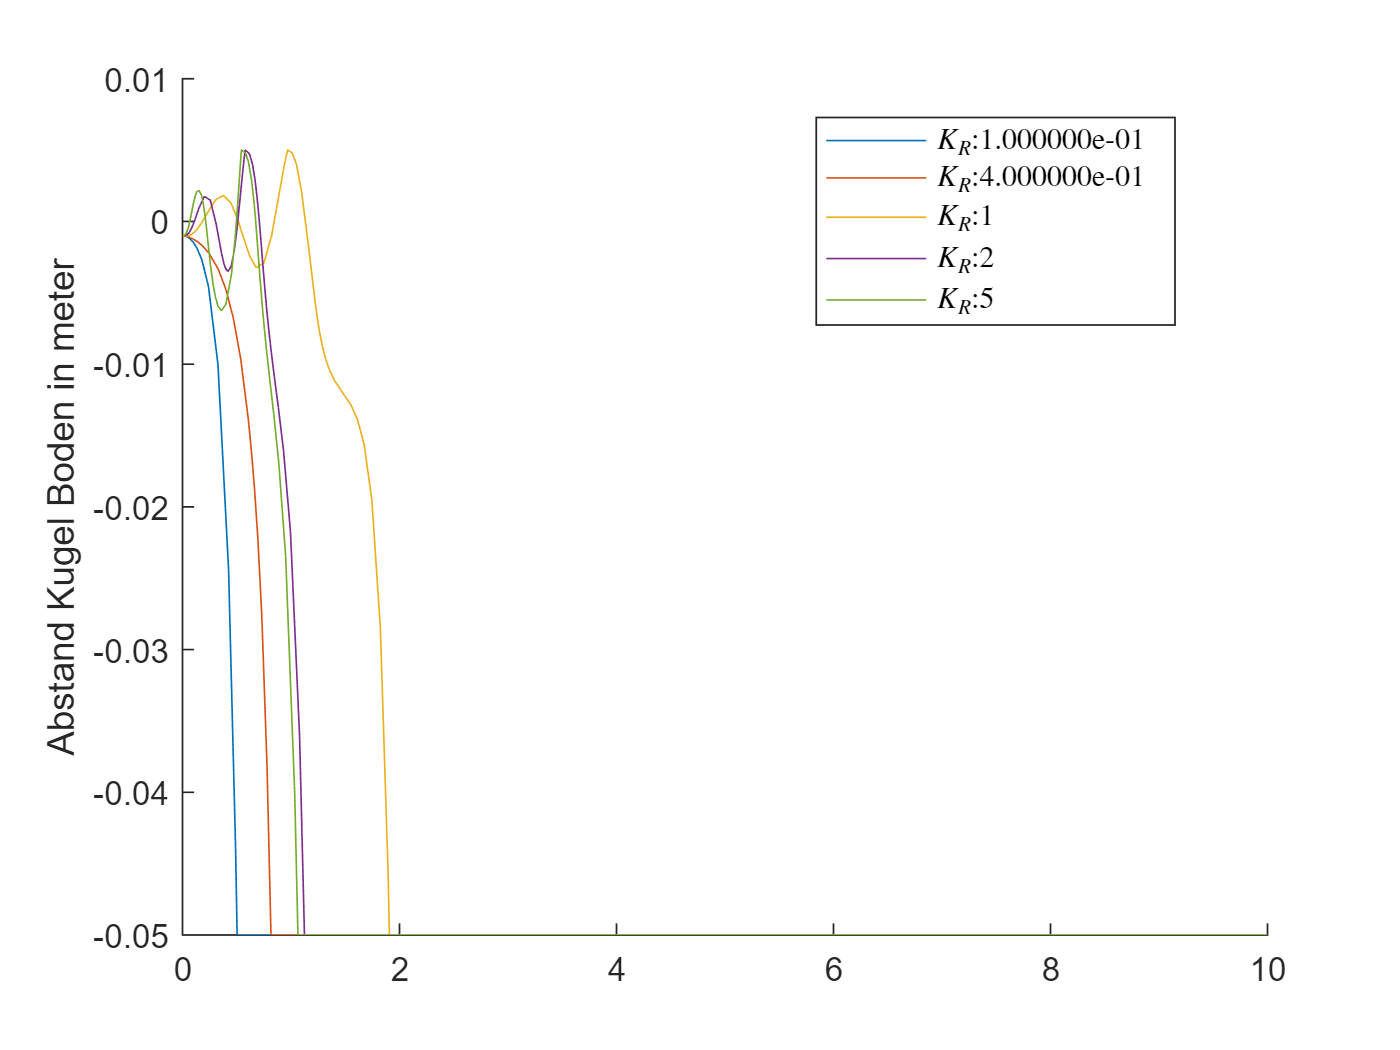

K_rs=[0.1,0.4,1,2,5];
figure
hold on
for i = 1:5
    K_r=K_rs(i)*1e3;
    simOut = sim('L5A2.slx');
    plot(get(simOut.logsout,"y").Values.Time,get(simOut.logsout,"y").Values.Data);
end
hold off
ylabel('Abstand Kugel Boden in meter')
legend(sprintf("$K_R$:%i",K_rs(1)), ...
    sprintf("$K_R$:%i",K_rs(2)), ...
    sprintf("$K_R$:%i",K_rs(3)), ...
    sprintf("$K_R$:%i",K_rs(4)), ...
    sprintf("$K_R$:%i", K_rs(5)), ...
    'Interpreter','latex','Location','best')

#### c)

Der misserable Versuch zur Bestimmung von $K_{R,kritisch}$ mit Hilfe einer Schleife:

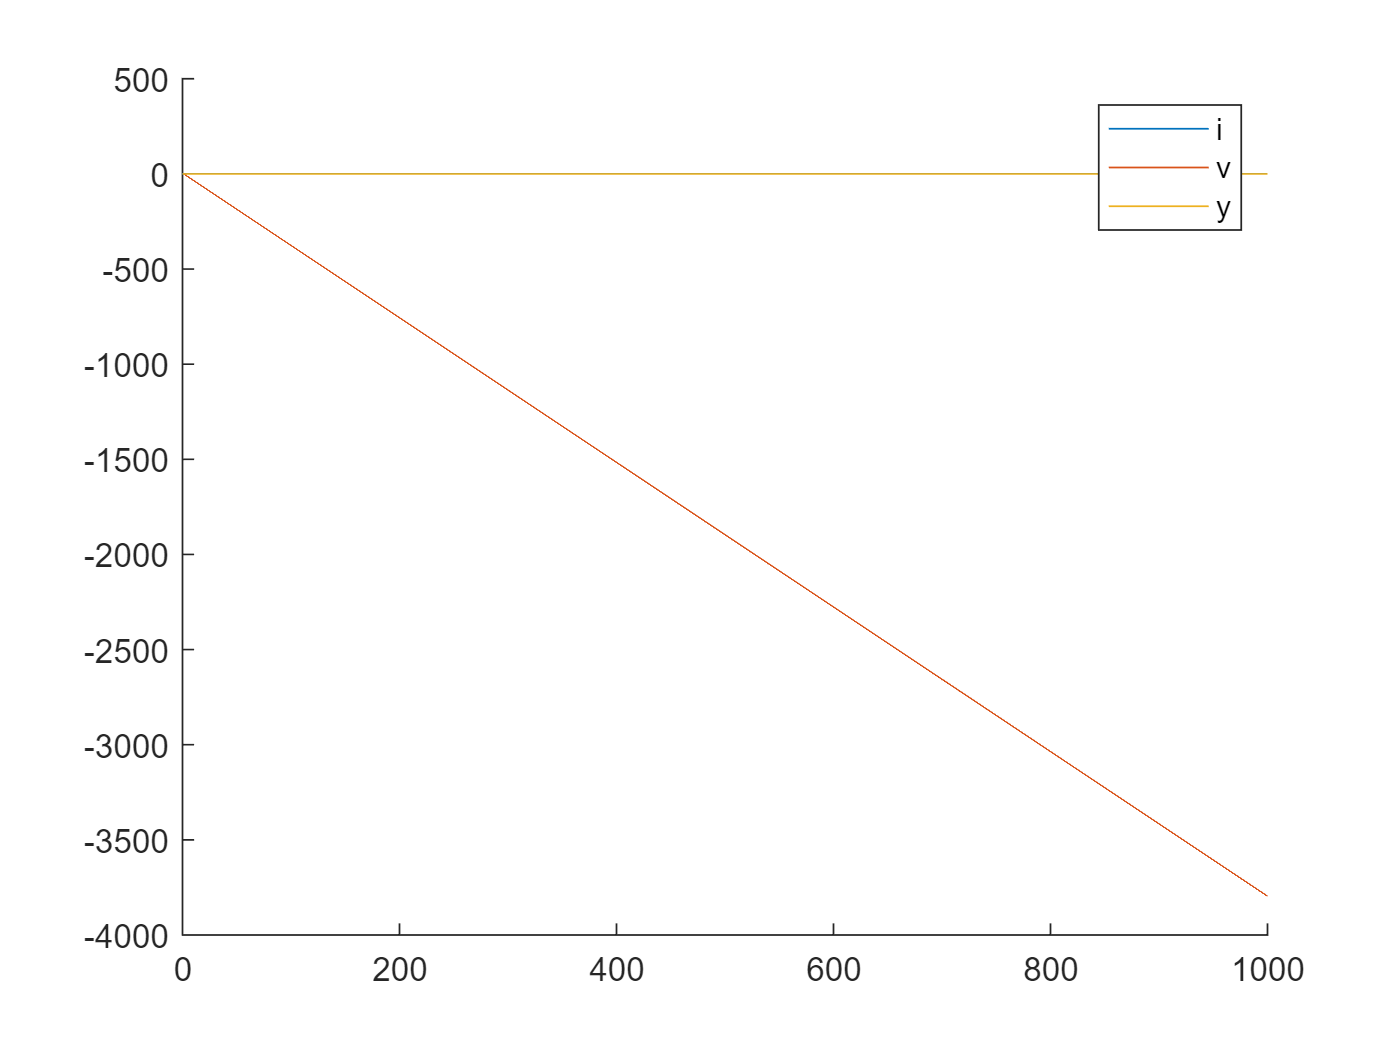

i=1000;
simOut = sim('L5A2.slx',1000);
while max(get(simOut.logsout,"y").Values.Data)<1e-3
    K_r=i
    i=i+1;
    plot(get(simOut.logsout,"y").Values.Time,get(simOut.logsout,"y").Values.Data);
    simOut = sim('L5A2.slx',1000);
end
% simOut = sim('L5A2.slx',10000);
figure
hold on
plot(get(simOut.logsout,"i").Values.Time,get(simOut.logsout,"i").Values.Data);
plot(get(simOut.logsout,"v").Values.Time,get(simOut.logsout,"v").Values.Data);
plot(get(simOut.logsout,"y").Values.Time,get(simOut.logsout,"y").Values.Data);
hold off
legend("i","v","y");

## Aufgabe 3

#### a)

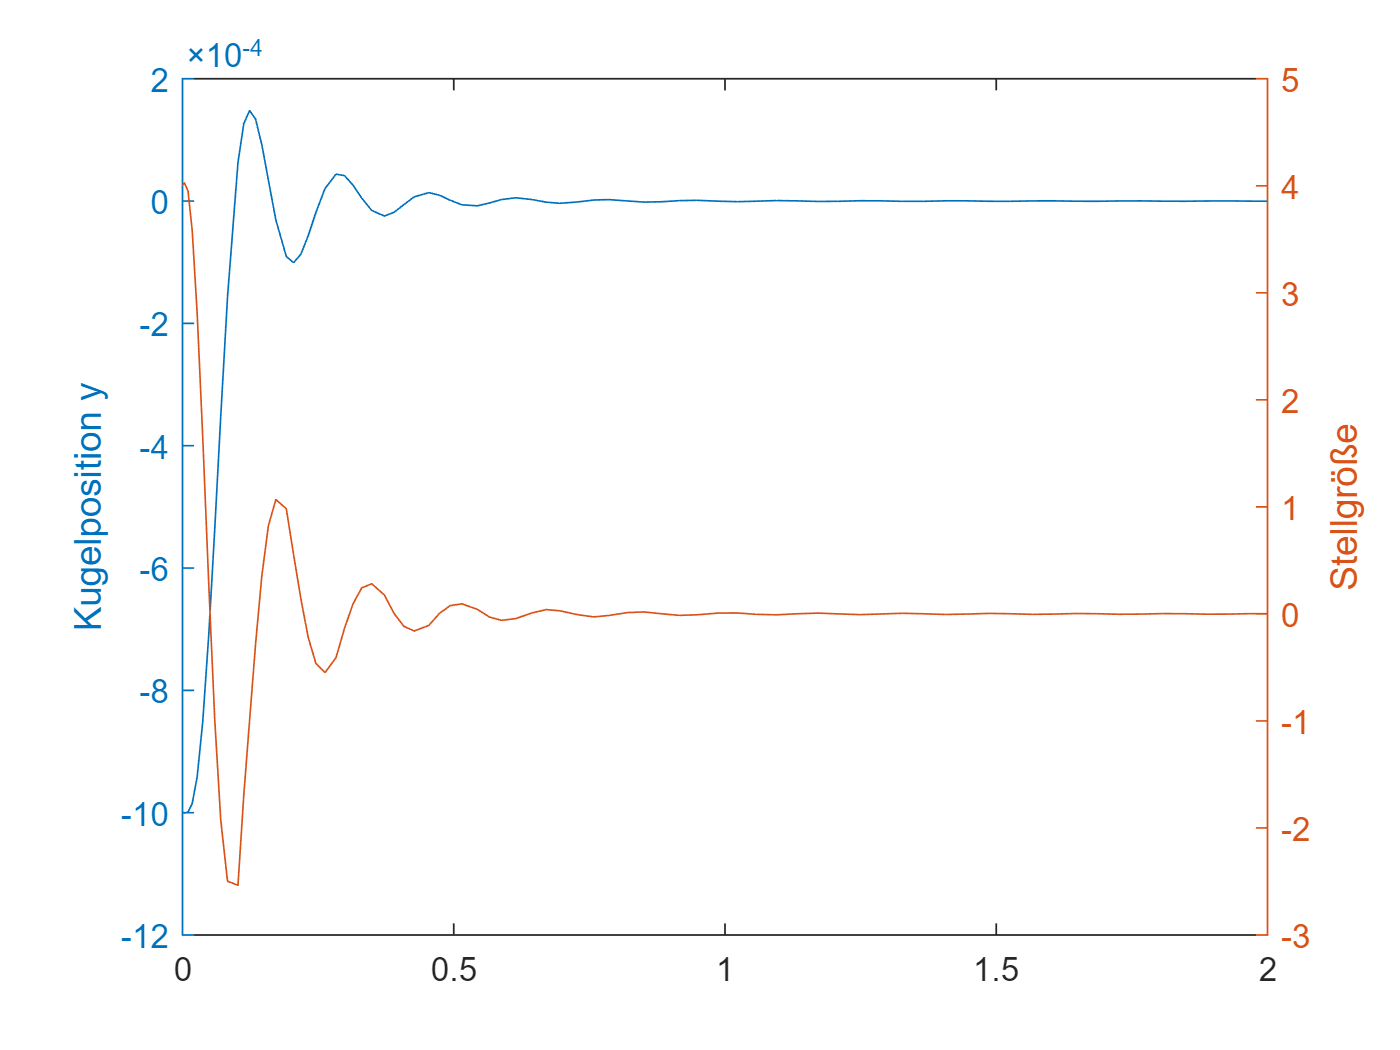

K_r=4e3;
T_v=0.05;
simOut = sim('L5A3.slx',2);
figure
yyaxis left
plot(get(simOut.logsout,"y").Values.Time,get(simOut.logsout,"y").Values.Data);
ylabel('Kugelposition y')
yyaxis right
plot(get(simOut.logsout,"Steuergröße").Values.Time,get(simOut.logsout,"Steuergröße").Values.Data);
ylabel('Stellgröße')

#### b)

Für $T_v >0\ldotp 02$ ist der Regelkreis stabil.

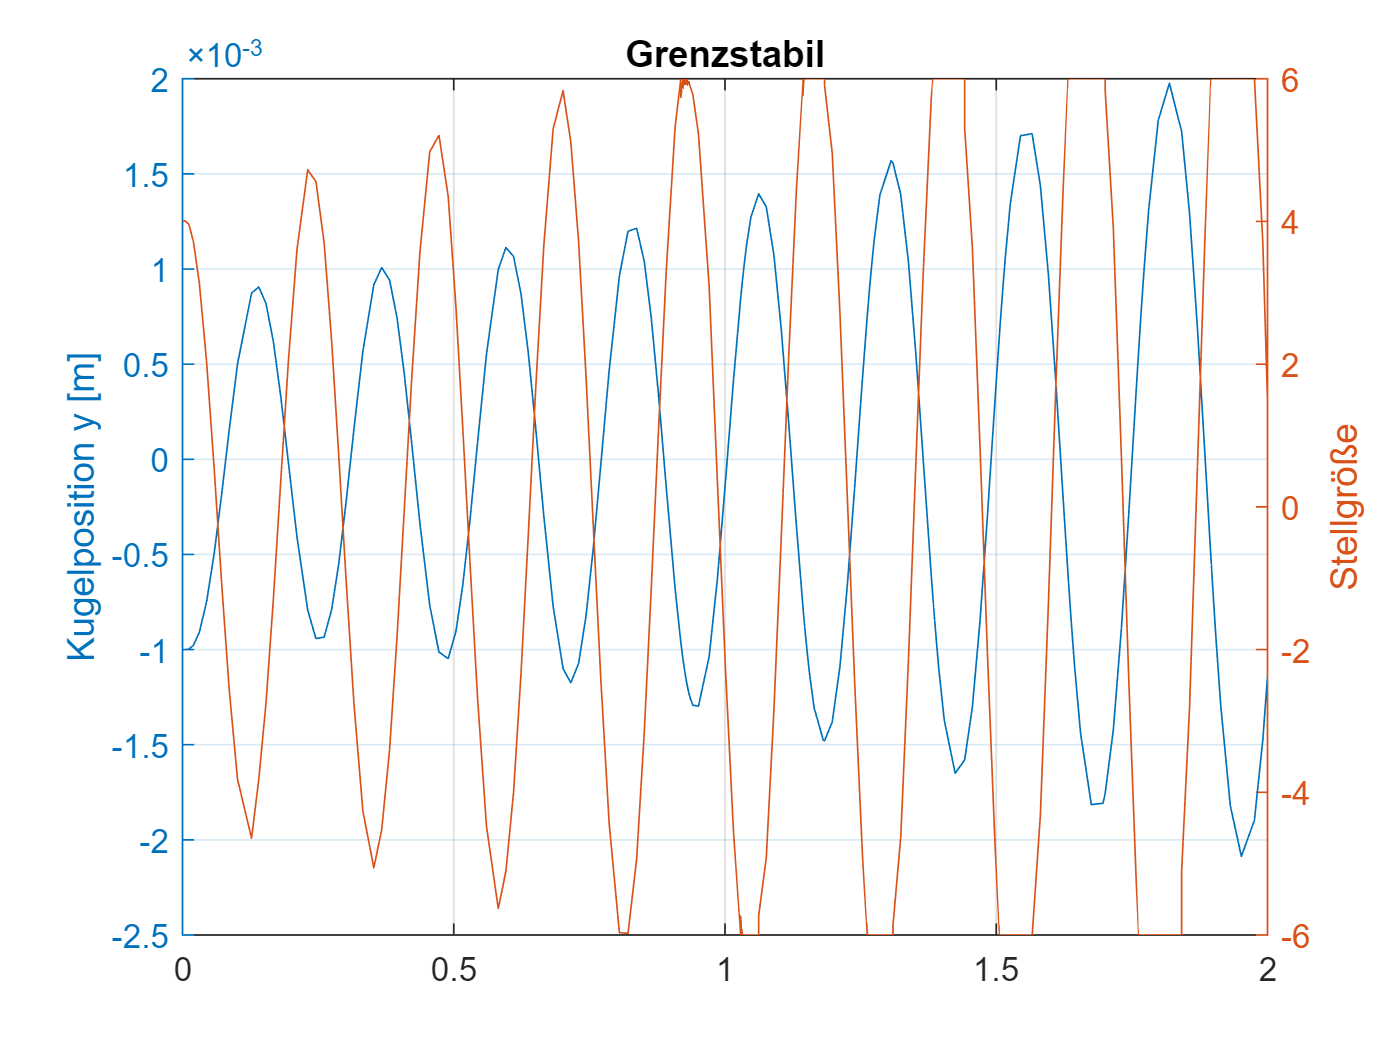

K_r=4e3;
T_v=0.02;
simOut = sim('L5A3.slx',2);
figure
yyaxis left
plot(get(simOut.logsout,"y").Values.Time,get(simOut.logsout,"y").Values.Data);
ylabel('Kugelposition y [m]')
yyaxis right
plot(get(simOut.logsout,"Steuergröße").Values.Time,get(simOut.logsout,"Steuergröße").Values.Data);
ylabel('Stellgröße')
ylim([-10 10])
grid on
title('Grenzstabil')

#### c)

Gedämpft, aber ohne Schwingung

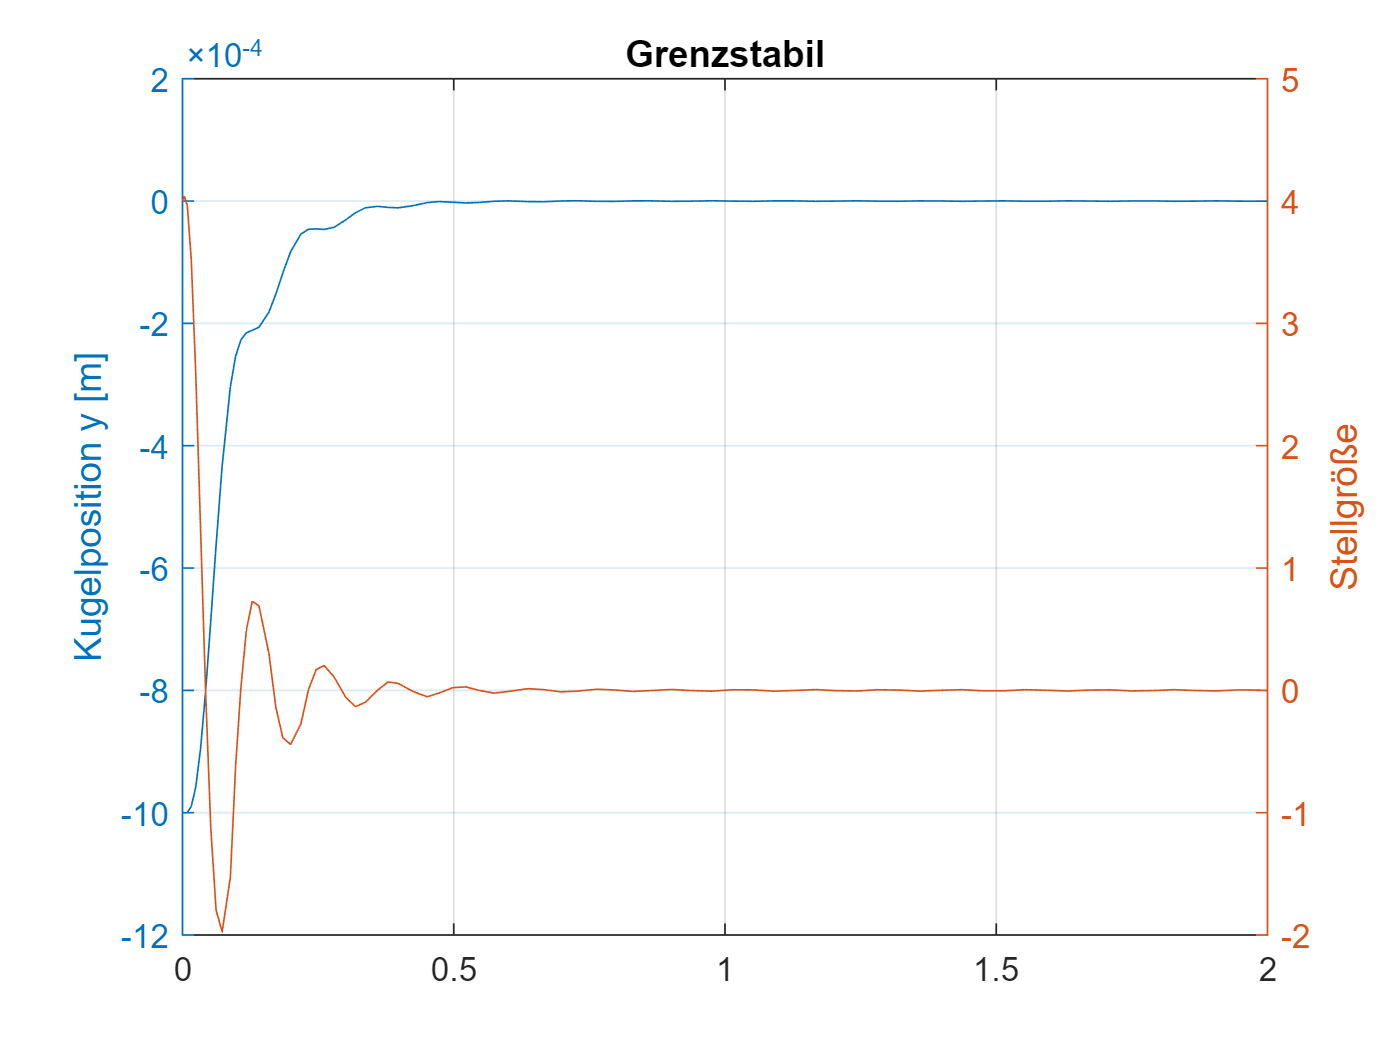

K_r=4e3;
T_v=0.08;
simOut = sim('L5A3.slx',2);
figure
yyaxis left
plot(get(simOut.logsout,"y").Values.Time,get(simOut.logsout,"y").Values.Data);
ylabel('Kugelposition y [m]')
yyaxis right
plot(get(simOut.logsout,"Steuergröße").Values.Time,get(simOut.logsout,"Steuergröße").Values.Data);
ylabel('Stellgröße')
grid on
title('Grenzstabil')